% Vandermonde matrix%
% Ill-conditioning
%
% Important result: any Vandermonde matrix of a large size is badly
% ill-conditioned unless its knots are more or less equally spaced 
% on or about the unit circle
% (https://arxiv.org/pdf/1504.02118.pdf)
%
clc, close all, clear all
n=5

n =      5


xv= rand(1, n);
xv

xv =       0.90467      0.88439      0.43899      0.78172      0.14847


A=vander(xv);
% matlab has a different ordering of columns, need fliplr to get the usual
% form
disp('A 5 x 5 Vandermonde matrix')

A 5 x 5 Vandermonde matrix


fliplr(A)

ans =             1      0.90467      0.81842       0.7404      0.66981
            1      0.88439      0.78214      0.69172      0.61175
            1      0.43899      0.19271     0.084599     0.037138
            1      0.78172      0.61109       0.4777      0.37343
            1      0.14847     0.022042    0.0032724   0.00048584


disp(" condition number of the Vandermonde matrix")

 condition number of the Vandermonde matrix


cond(A)

ans =         18862


%


m=  10;
cA=zeros( 1, m);
for n=1:1:m
    xv= linspace(0, 1, n);
    % % for DFT matrix,  uncomment  the next two lines
     %  omega= exp( -2*pi*sqrt(-1)/n);
     %  xv= omega.^(0:n-1);
   %  A=vander(xv);
   A= hilb(n);
    cA(n)= cond(A);
end
format shortg 
disp("Showing size and  conditon numbers of Vandermonde matrices")

Showing size and  conditon numbers of Vandermonde matrices


disp([ (1:m); cA]')

            1            1
            2       19.281
            3       524.06
            4        15514
            5   4.7661e+05
            6   1.4951e+07
            7   4.7537e+08
            8   1.5258e+10
            9   4.9315e+11
           10   1.6025e+13



semilogy( cA, 'ro')
hold on
semilogy(cA, 'LineWidth', 2)
pm= polyfit( 5:m/5, log(cA(5:m/5)), 1);

slope= pm(1);
disp(['condition number grows approximately as exp(', num2str(slope/5),' n)'])

condition number grows approximately as exp(0 n)


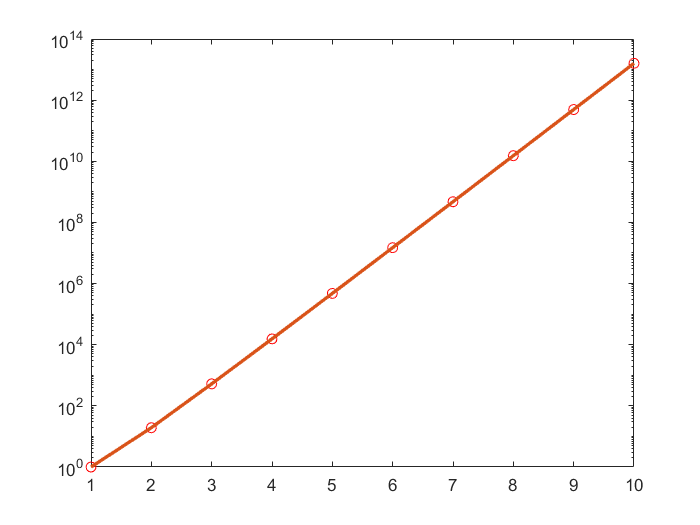

hold off